close all
clearvars

% ==============================================

im = imread('object.jpg');
im = im2double(im);
im = 1 - im;
imshow(im)

S = strel('disk', 3);

Erd = imerode(im, S);
imshow(Erd)

Dil = imdilate(im, S);
imshow(Dil)

Cls = imclose(im, S);
imshow(Cls)

Opn = imopen(im, S);
imshowpair(Opn, im)

close all
clearvars
% =================================================

im = imread('cygnus.tif');
im = im2double(im);

imshow(im)

S = strel('disk', 5);
I = imopen(im, S);
imshow(I)

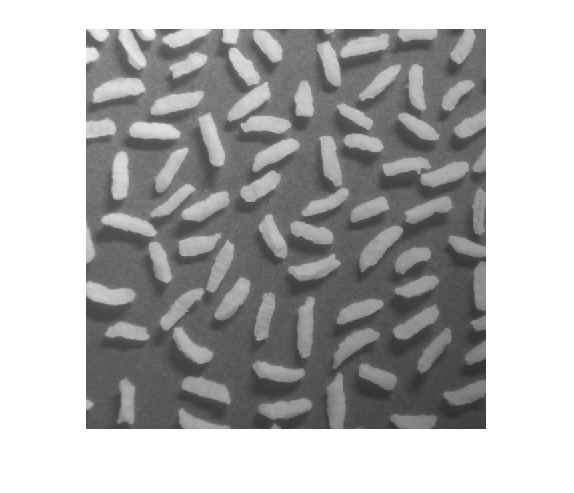

close all
clearvars
% ====================================================

im = imread('rice.tif');
im = im2double(im);

imshow(im)

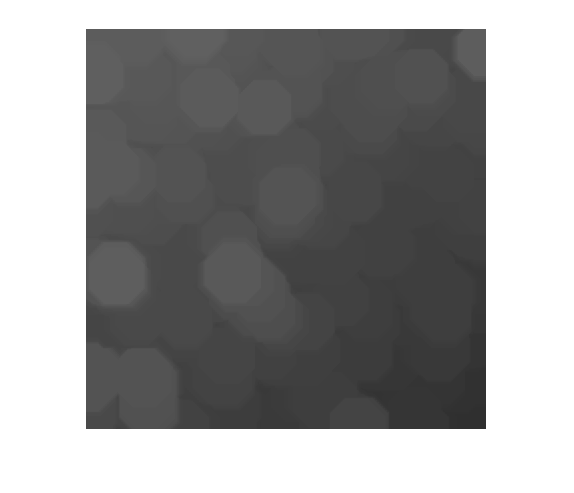



Im = im;

se = strel('disk', 40);
I = imopen(Im, se);
imshow(I)

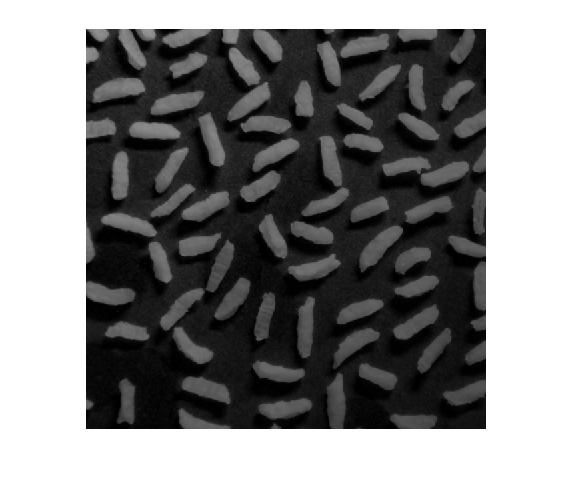


Im = im - I;
imshow(Im)

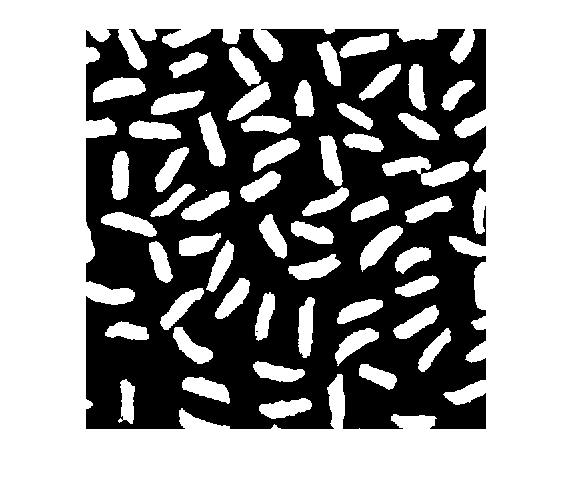


Th = graythresh(Im);
Im(Im(:, :) < Th) = 0;
Im(Im(:, :) >= Th) = 1;

imshow(Im, [])

close all
clearvars
% =========================================

im = imread('text.png');
im = im2double(im);

imshow(im)

se = strel('square', 10);
Im = imopen(im, se);
imshow(Im)

I = im - Im;
imshow(I)
imhist(I)

Th = graythresh(I);

I(I(:, :) >= Th) = 1;
I(I(:, :) < Th) = 0;

imshow(I)

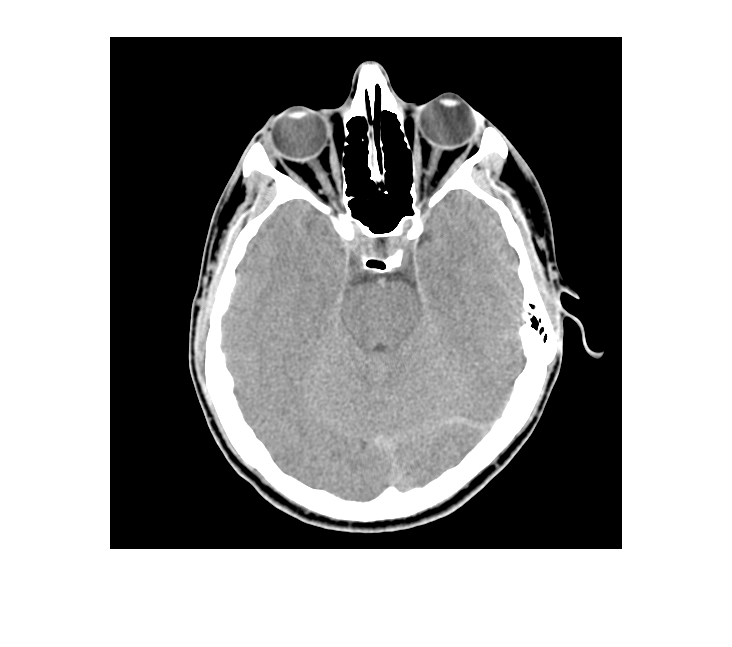

% ______ gradiant _______
close all
clearvars
% ===================================

im = imread('brain.tif');
im = im2double(im);
imshow(im)

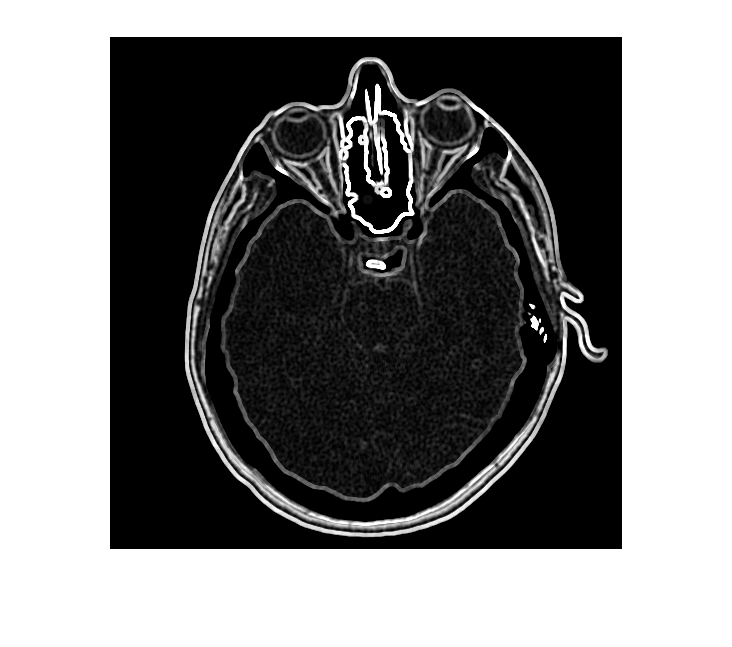


se = strel('disk', 5);
I = imdilate(im, se);

I = I - im;
imshow(I, [])

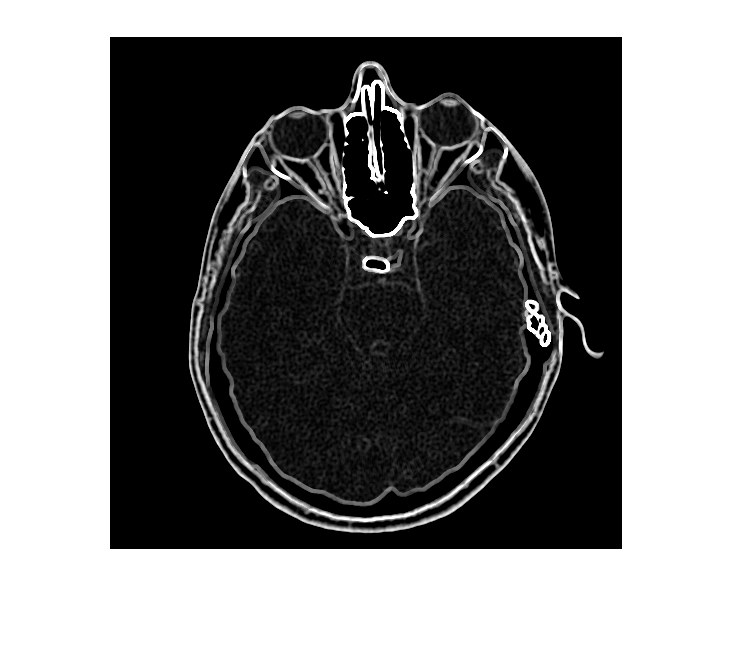


se = strel('disk', 5);
I = imerode(im, se);
I = im - I;
imshow(I, [])

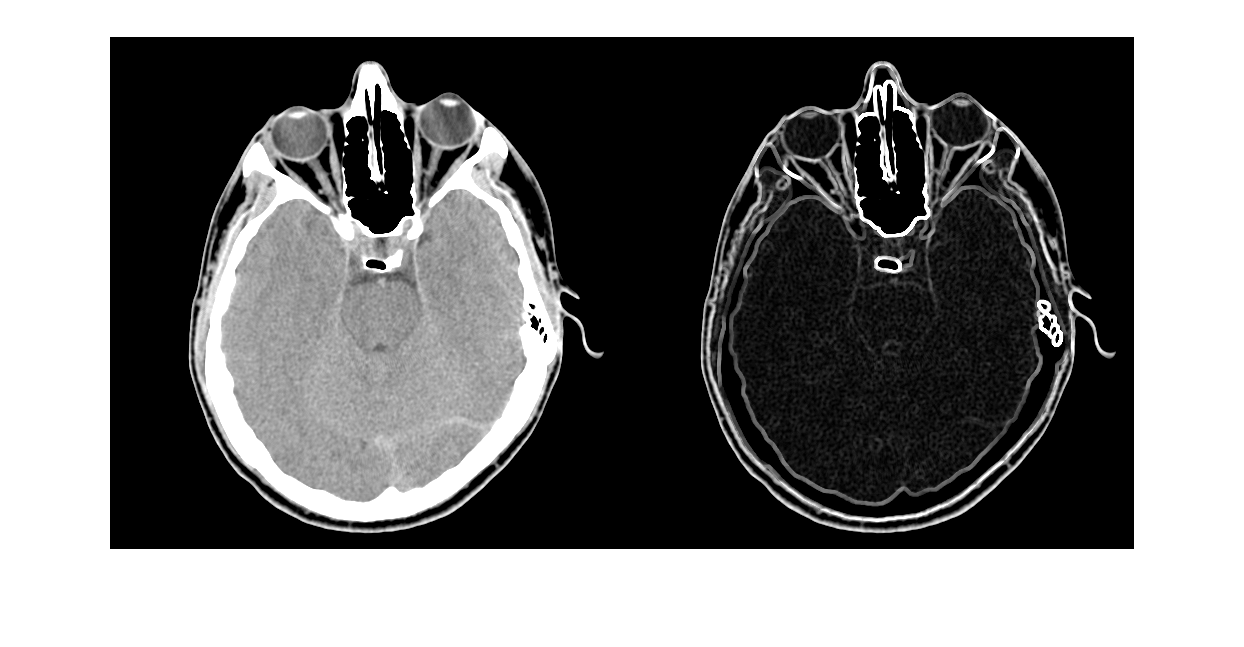


imshowpair(im, I, 'montage')

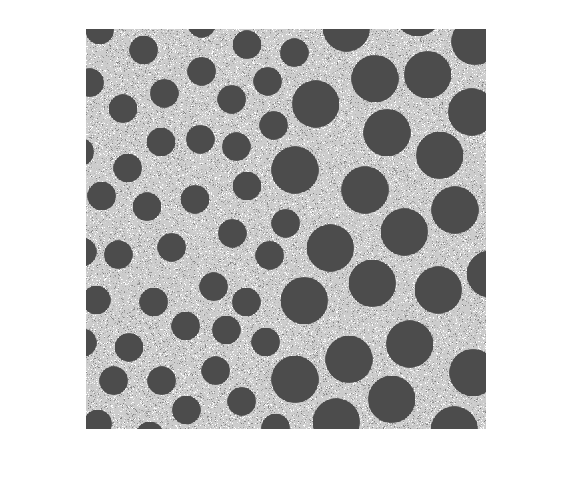

% __________ Segmentation __________
close all
clearvars

% ====================================================

im = imread('blobs.tif');
im = im2double(im);
imshow(im)

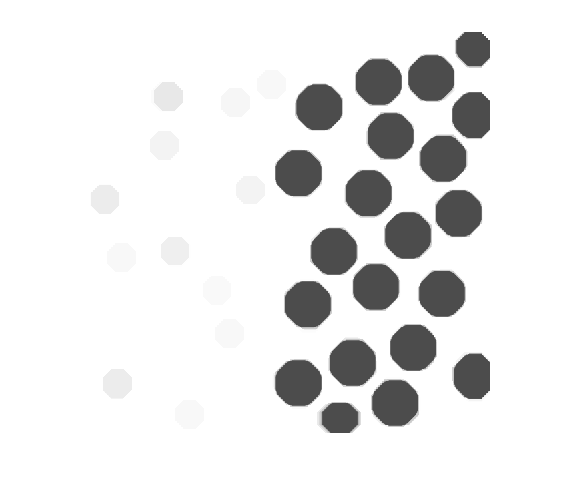


se = strel('disk', 22);
I = padarray(im, [5 5], 1, 'both');
I = imclose(I, se);
imshow(I)

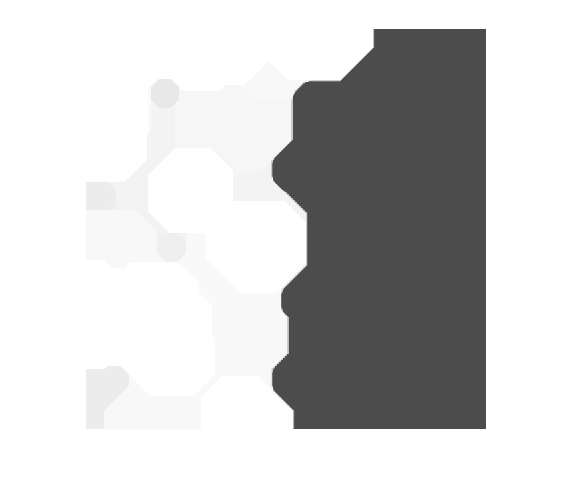


I = I(6:end-5, 6:end-5);
se2 = strel('disk', 60);
I2 = imopen(I, se2);
imshow(I2)

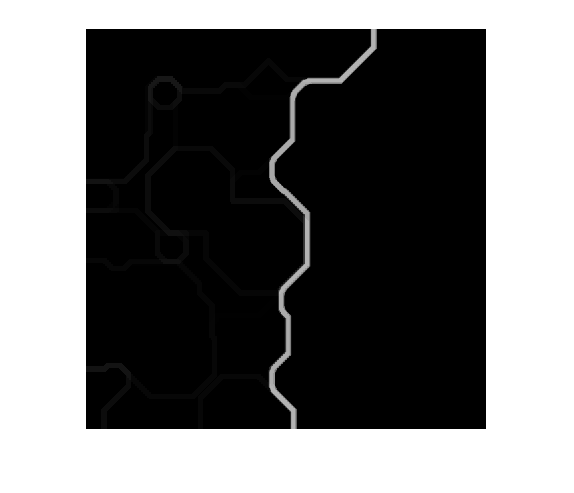


SE = strel('disk', 5);

Bound = imdilate(I2, SE) - imerode(I2, SE);
imshow(Bound)

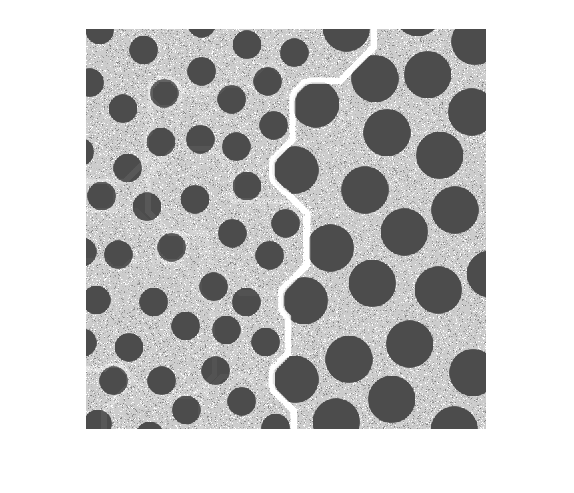


imshow(Bound + im)

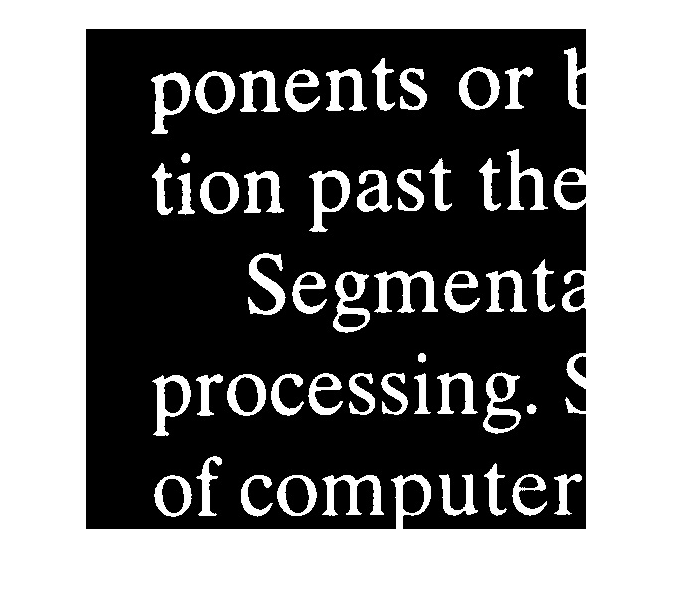

% _____ Extract Border ______
close all
clearvars
% ===============================================
 im= imread('border.jpg');
 im = rgb2gray(im);
 im = im2double(im);
 
 imshow(im)

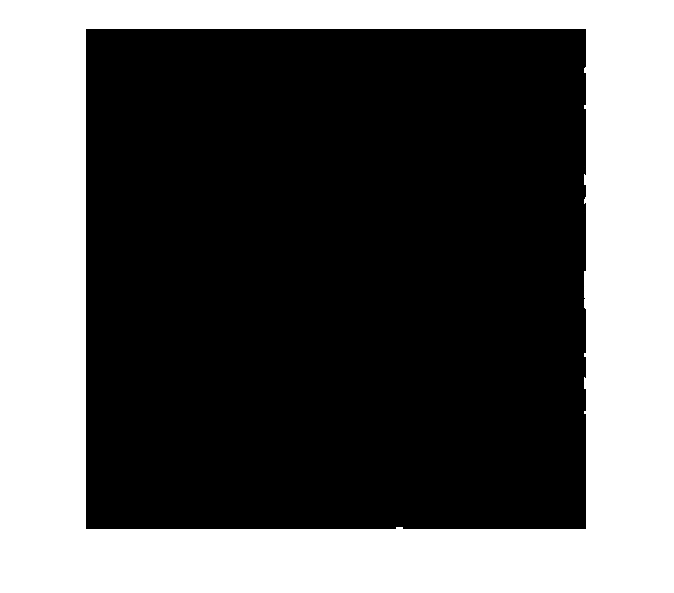

 
 I = im;
 I(2:end-2, 2:end-2) = 0;
 imshow(I)

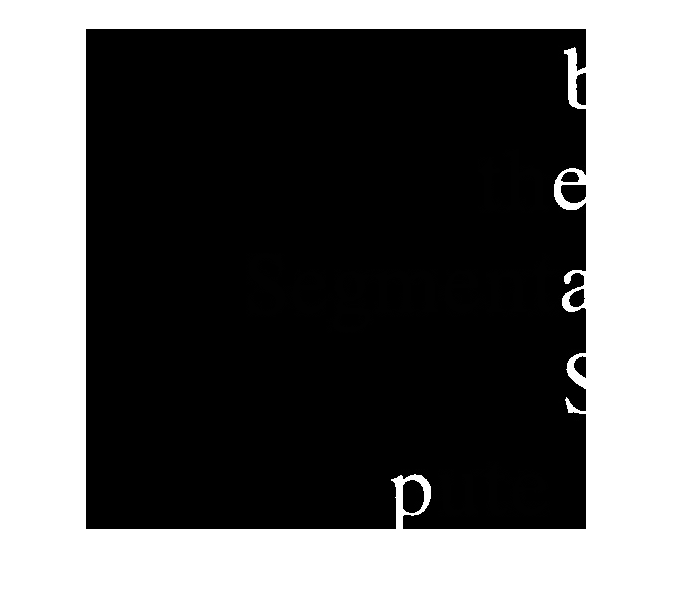

 
 se = strel('square', 3);
 I = imdilate(I, se);
 
 I2 = imreconstruct(I, im);
 imshow(I2)

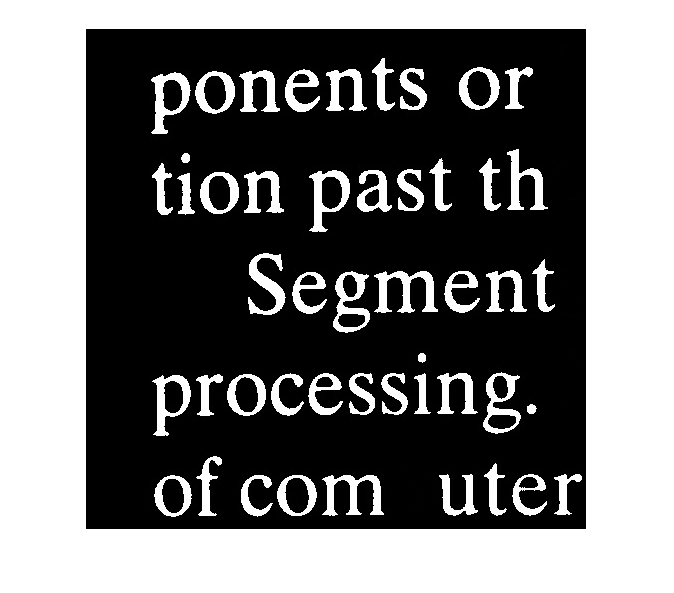

 
 I3 = im - I2;
 imshow(I3)

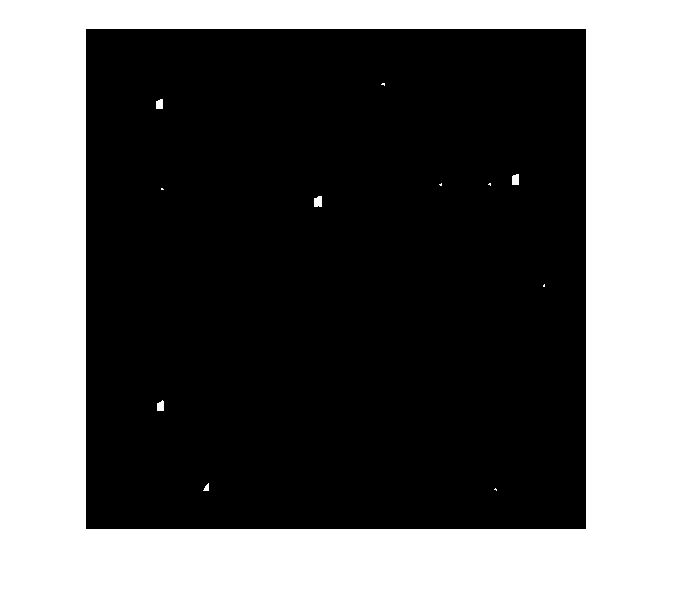

 
 se = strel('line', 51, 90);
 I4 = imerode(I3, se);
 imshow(I4)

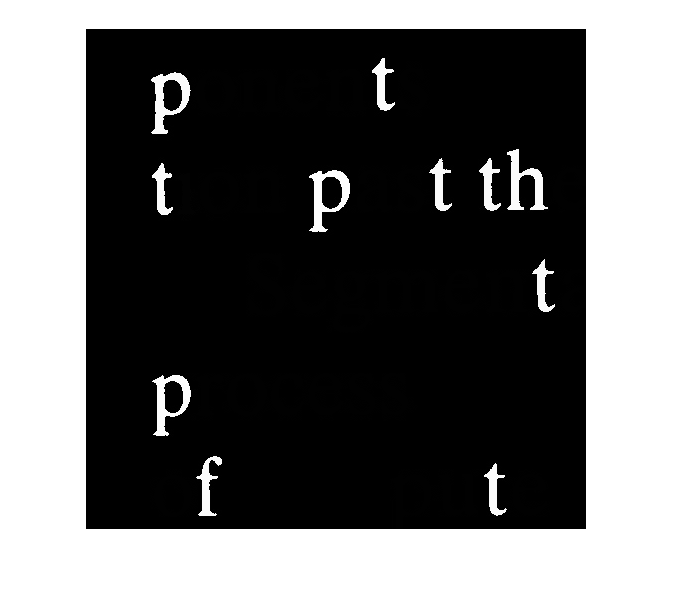

 
 I5 = imreconstruct(I4, im);
 imshow(I5)

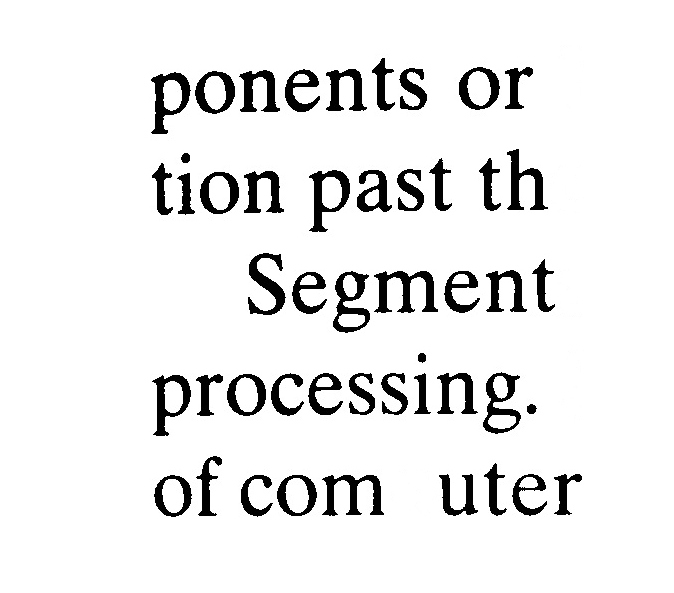

 
 % Filling the hole
 
 Ineg = 1 - I3;
 imshow(Ineg)

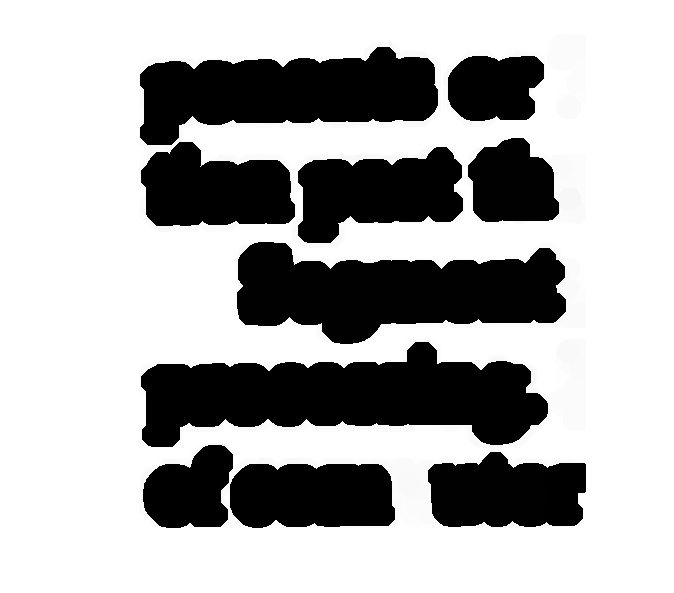

 
 se = strel('disk', 12);
 Ierd = imerode(Ineg, se);
 imshow(Ierd)

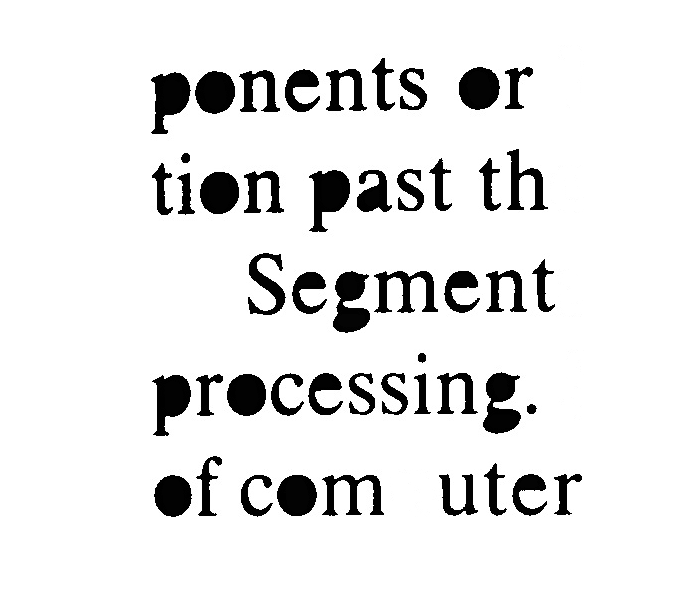

 
 imshow(imreconstruct(Ierd, Ineg))

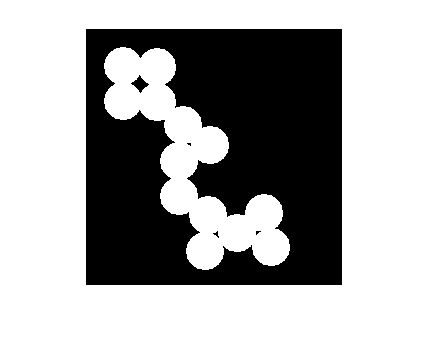

% bwmorph, imfill
 BW = imread('circles.png');
imshow(BW);

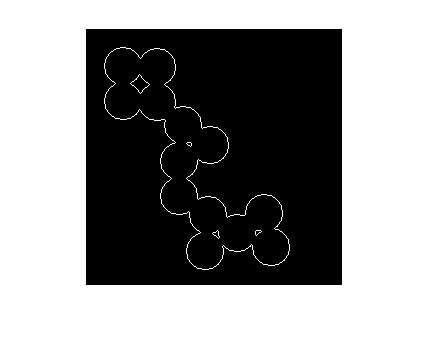


BW2 = bwmorph(BW,'remove');
figure
imshow(BW2)

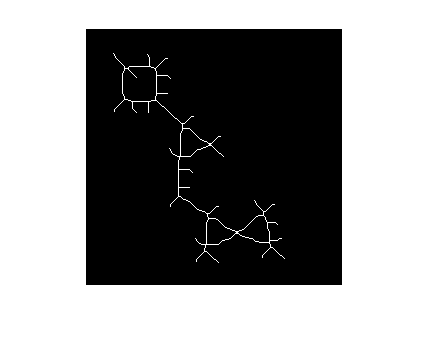


BW3 = bwmorph(BW,'skel',Inf);
figure
imshow(BW3)